clear all
clc
%% System Setup
Ts = 1/8000;  % Sampling time duration in seconds
Fs = 1/Ts; % Sampling frequency in Hz
T = 10; % Simulation time duration
t = 0:Ts:T-Ts; % sampled time

%% Carrier
Ac = 1; % Carrier amplitude
fc = 1000; % Carrier frequency
ct = cos(2*pi*fc*t); % Carrier signal with amplitude 1
 
%% Message 
fm = 100; % Message frequency
A = 0.5; % Message amplitude
mt = cos(2*pi*fm*t); % Message signal with amplitude 1

Modulation:

utam = (A*mt+Ac).*ct; % Conventional AM
utdsb = (A*mt*Ac).*ct; % DSB SC

%%SSB Signal:
mcomplex=hilbert(mt) ;
utssb=mcomplex.*exp(1j*2*pi*fc*t) ;

Plots in time domain of all types of modulated signal :

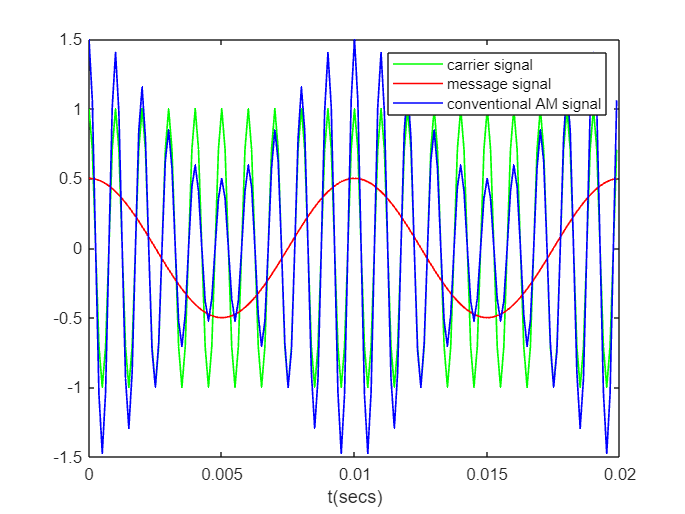

%% Plotting - Time Domain
hold off;  
plot(t(1:20/(Ts*fc)), ct(1:20/(Ts*fc)),'g','DisplayName','carrier signal','LineWidth',1); hold on;
plot(t(1:20/(Ts*fc)),A*mt(1:20/(Ts*fc)),'r','DisplayName','message signal','LineWidth',1); hold on;
plot(t(1:20/(Ts*fc)), utam(1:20/(Ts*fc)),'b','DisplayName','conventional AM signal','LineWidth',1);
legend("show")
xlabel("t(secs)") ;
hold off;  

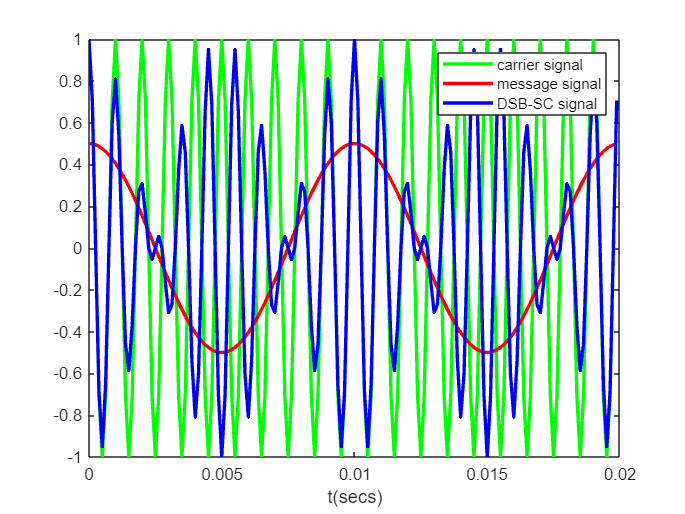

plot(t(1:20/(Ts*fc)), ct(1:20/(Ts*fc)),'g','DisplayName','carrier signal','LineWidth',2); hold on;
plot(t(1:20/(Ts*fc)),0.5*mt(1:20/(Ts*fc)),'r','DisplayName','message signal','LineWidth',2); hold on;
plot(t(1:20/(Ts*fc)), utdsb(1:20/(Ts*fc)),'b','DisplayName','DSB-SC signal','LineWidth',2);
xlabel("t(secs)") ;
legend("show")

Plots of various signals in frequency domain:

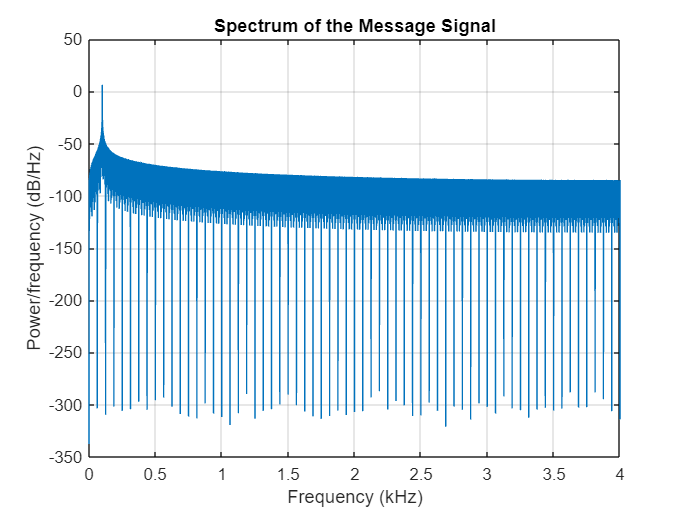

%% Plotting - Frequency Domain
Hs = spectrum.periodogram;
figure;
psd(Hs,A*mt,'Fs',Fs)
title('Spectrum of the Message Signal')

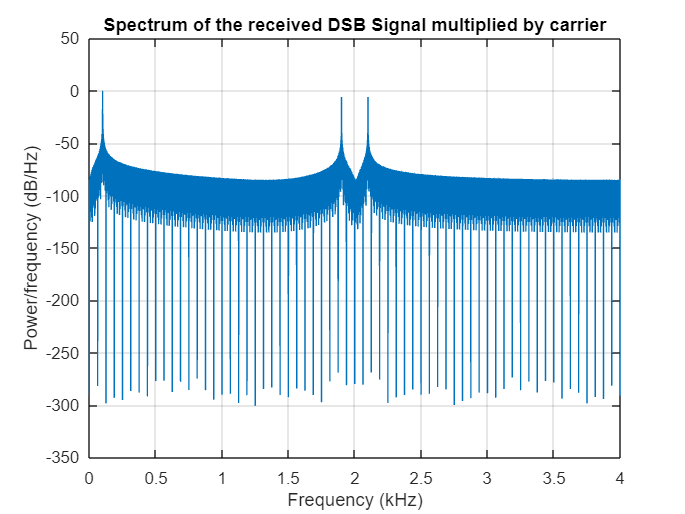

figure;
psd(Hs,ct,'Fs',Fs)
title('Spectrum of the Carrier Signal')

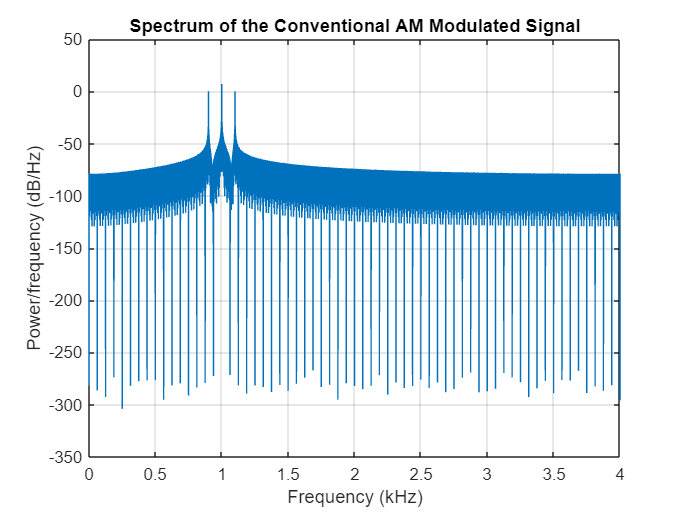

figure; 
psd(Hs,real(utam),'Fs',Fs)
title('Spectrum of the Conventional AM Modulated Signal')

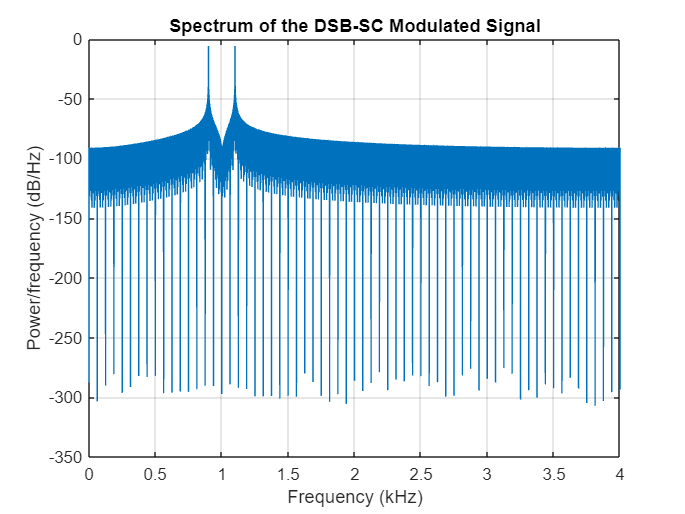

figure; 
psd(Hs,real(utdsb),'Fs',Fs)
title('Spectrum of the DSB-SC Modulated Signal')

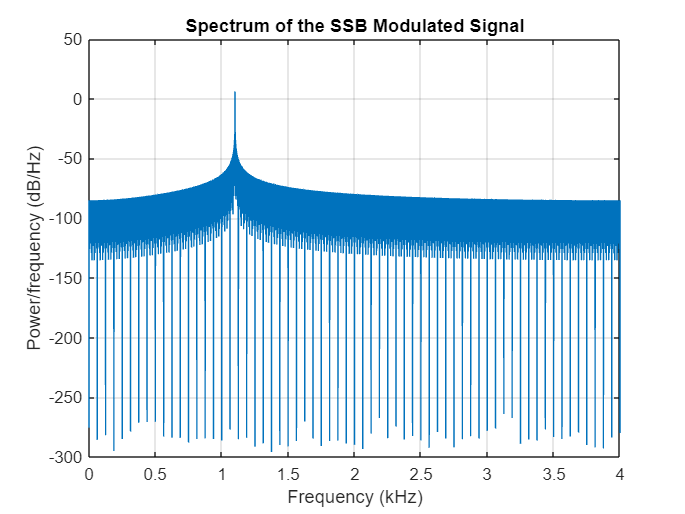

figure; 
psd(Hs,real(utssb),'Fs',Fs)
title('Spectrum of the SSB Modulated Signal')

1.Demodulation of Conventional AM :

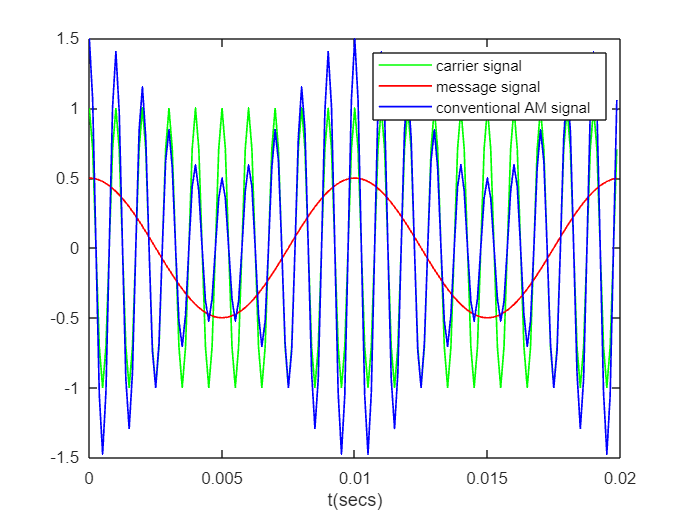

%%Conventional AM :(using squaring+low pass filtering+scaling)
rtam=utam ;
rtsq=rtam.*rtam ;
rftam=lowpass(rtsq,fm,Fs) ;
mestam=sqrt(2*rftam) ;%appropriate scaling.
plot(t(1:50/(Ts*fc)), mestam(1:50/(Ts*fc))-Ac,'b','DisplayName','demodulated signal','LineWidth',2);
title("Estimated messsage") ;
xlabel("t(secs)") ;
ylabel("m_{estimate}(t)") ;

2.Demodulation of DSB-SC/SSB using "coherent detector" :

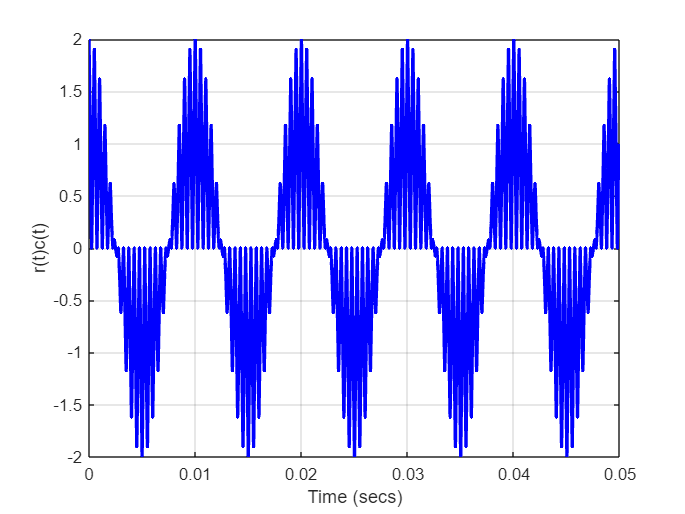

%%Coherent Detector :
rt=utdsb ;
%%Multiplication with Carrier
rmct=rt.*(2*ct) ;
plot(t(1:50/(Ts*fc)), rmct(1:50/(Ts*fc)),'b','DisplayName','demodulated signal','LineWidth',2);
grid on
xlabel("Time (secs)")
ylabel("r(t)c(t)")

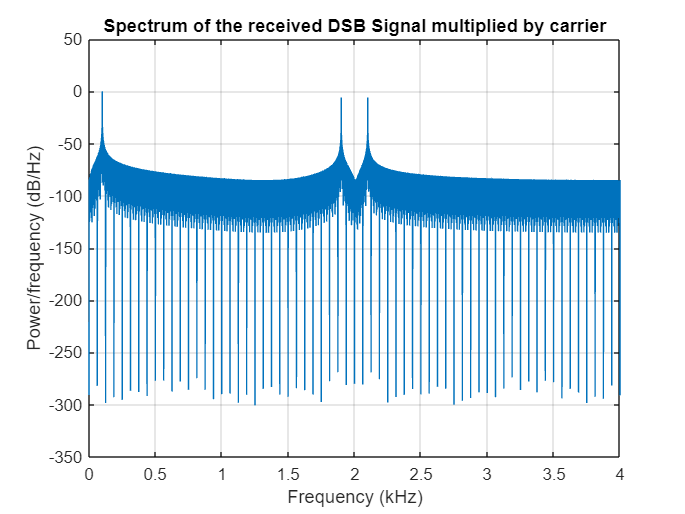

psd(Hs,real(rmct),'Fs',Fs) 
title('Spectrum of the received DSB Signal multiplied by carrier')

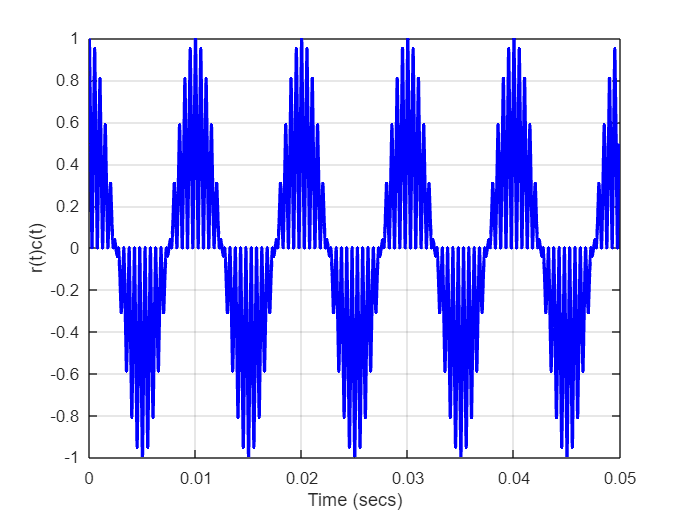

%%Low pass filtering.
rft=lowpass(rmct,fm,Fs) ;
psd(Hs,real(rft),'Fs',Fs) 
title('Spectrum of the Above Signal after low pass filtering')

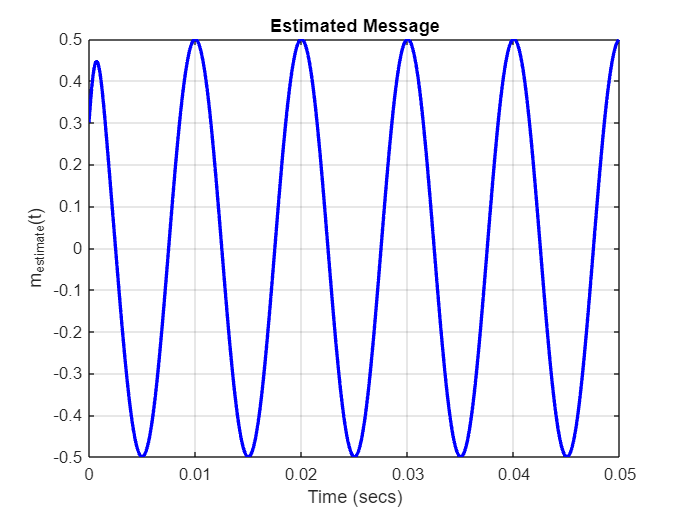

%%Plotting the estimated message from this filtered rft:
plot(t(1:50/(Ts*fc)), rft(1:50/(Ts*fc)),'b','DisplayName','demodulated signal','LineWidth',2);
grid on
title("Estimated Message")
xlabel("Time (secs)")
ylabel("m_{estimate}(t)")

Observations:

1.For Coherent Detection :This works very well and is fairly close to the original message i.e. $m\left(t\right)=0\ldotp 5\cos \left(2\pi f_m t\right)\;$as can be seen from the plot of mestimate(t).

2.For Conventional AM : Squaring and Low pass filtering was used to demodulate the received signal.This was also found to work satisfactorily.Also it can be verified that modulation index given by A{min(m(t)}/Ac must be 1.For example,if the variable A is changed to a value >1 since Ac=1,the reproduced signal does not converge to the original message.Thus,this model replicates the behaviour of an envelope detector and is hence,valid method of conventional AM demodulation.

3.For SSB :Even though not shown above,the SSB signal once generated(as shown above) can be demodulated in the same manner as DSB-SC by using coherent demodulator.